# Verification of the implementation

## Introduction

This example is only a verification of the function eigenBridge2.m based on the works of [1]. For this reason, I use a slightly different function whose only purpose is to verifiy the numerical implementation. The function I use here is : eigenBridge_Verification.m

First, the eigen-frequencies are computed in a table in a similar fashion as table 1 and 2 from [1]. Then the evolution of the eigen-frequencies is shown  as a function of $\mu$ and $\lambda
$ (fig. 2 from [1]). Finally,  the mode shapes are potted for different values of $\lambda
$ and $\mu$ (fig. 3 and 44 from [1])

[1] Luco, J. E., & Turmo, J. (2010).|Linear vertical vibrations of suspension bridges:A review of continuum models and some new results| . *Soil Dynamics and Earthquake Engineering*, 30(9), 769-781.

## Eigen frequencies calculation

Mode-shapes and eigen-frequencies are calculated for every combination of $\lambda
$ and $\mu$ . The separation between anti-symmetric and symmetric mode  shapes and eigen frequencies is  also done.

clearvars; close all;clc;

% Following Table 1 in [1], we have:
lambda = sqrt([0,100,225,1e8]); % 1e8 instead of  + infinity
mu = sqrt([0,1e-5,1e-4,5e-4,1e-3,2.5e-3,5e-3,1e-2,2.5e-2,5e-2,0.1]);
Nmodes = 4; % I only want 4 modes here
Nyy=200; % Number of integration points for deck span
% Non-dimensional deck span x/L, where L = span length
x = linspace(0,1,Nyy); 

% Preallocation
w_s = zeros(numel(lambda),numel(mu),Nmodes);
w_a = zeros(numel(lambda),numel(mu),Nmodes);
phi_s = zeros(numel(lambda),numel(mu),Nmodes,Nyy);
phi_a = zeros(numel(lambda),numel(mu),Nmodes,Nyy);

% Calculation of eigen frequencies and mode shapes
tic
for ii=1:numel(lambda)
    for jj=1:numel(mu)
        [w_a(ii,jj,:),w_s(ii,jj,:),phi_a(ii,jj,:,:),phi_s(ii,jj,:,:)] = ...
            eigBridge_Verification(mu(jj),lambda(ii),Nmodes,x);
    end
end
toc

Elapsed time is 21.438467 seconds.


## Reproduction of Table 1 in Luco et al [1]

We display the eigen frequencies in the workspace. A comparison with Table 1 in [1] shows a good agreement, which suggests that the implementation of the code is fine.

varNames = {'mu_squared','lambda_0','lambda_100','lambda_225','lambda_inf','Anti_symmetric'};
varTypes = {'double','double','double','double','double','double'};
for ii=1:Nmodes
    T2 = table('Size',[numel(mu),numel(lambda)+2],'VariableTypes',varTypes,'VariableNames',varNames);
    for jj=1:numel(lambda)+2
        if jj==1
            T2(:,jj) = num2cell(mu.^2');
        elseif jj == numel(lambda)+2
            T2(:,jj) = num2cell(squeeze(w_a(jj-2,:,ii)./pi)');
        else
            T2(:,jj) = num2cell(squeeze(w_s(jj-1,:,ii)./pi)');
        end
    end
    fprintf(['mode no. ',num2str(ii),' \n'])
    disp(T2)
end

mode no. 1 


    mu_squared    lambda_0    lambda_100    lambda_225    lambda_inf    Anti_symmetric
    __________    ________    __________    __________    __________    ______________

           0            1       2.5971        2.7878        2.8607               2    
       1e-05            1        2.598        2.7887        2.8619          2.0004    
      0.0001       1.0005       2.6041        2.7989        2.8734          2.0039    
      0.0005       1.0025       2.6308        2.8435         2.923          2.0196    
       0.001       1.0049       2.6608        2.8973        2.9842          2.0391    
      0.0025       1.0123       2.7352        3.0488        3.1605          2.0964    
       0.005       1.0244       2.8205        3.2713        3.4336          2.1885    
        0.01

mode no. 2 


    mu_squared    lambda_0    lambda_100    lambda_225    lambda_inf    Anti_symmetric
    __________    ________    __________    __________    __________    ______________

           0            3       3.4798        4.4621        4.9182               4    
       1e-05       3.0013       3.4804        4.4646        4.9243          4.0032    
      0.0001       3.0133        3.488        4.4853        4.9784          4.0315    
      0.0005       3.0659       3.5202        4.5588        5.2123          4.1549    
       0.001       3.1304         3.56        4.6215        5.4905          4.3043    
      0.0025       3.3164         3.68        4.7285        6.2516           4.724    
       0.005       3.6052       3.8907        4.8335        7.3466           5.351    
        0.01

mode no. 3 


    mu_squared    lambda_0    lambda_100    lambda_225    lambda_inf    Anti_symmetric
    __________    ________    __________    __________    __________    ______________

           0            5       5.0525        5.3024        6.9417               6    
       1e-05       5.0062       5.0586        5.3069        6.9586          6.0106    
      0.0001       5.0613       5.1127        5.3473        7.1075          6.1057    
      0.0005       5.2995        5.346        5.5306        7.7352          6.5112    
       0.001       5.5829       5.6252        5.7678        8.4546          6.9851    
      0.0025       6.3578       6.3913        6.4754        10.315          8.2448    
       0.005       7.4728       7.4991        7.5513        12.831          9.9978    
        0.01

mode no. 4 


    mu_squared    lambda_0    lambda_100    lambda_225    lambda_inf    Anti_symmetric
    __________    ________    __________    __________    __________    ______________

           0            7       7.0149        7.0487        8.9547               8    
       1e-05       7.0169       7.0318        7.0652        8.9907          8.0252    
      0.0001       7.1673       7.1817        7.2132        9.3058          8.2488    
      0.0005       7.8005       7.8132        7.8384        10.594          9.1768    
       0.001       8.5262       8.5377        8.5578        12.011          10.219    
      0.0025       10.404       10.413        10.427        15.505          12.848    
       0.005       12.942       12.949        12.958        20.015          16.313    
        0.01

## Variation of eigen frequencies

Figure 2 from [1] is reproduced

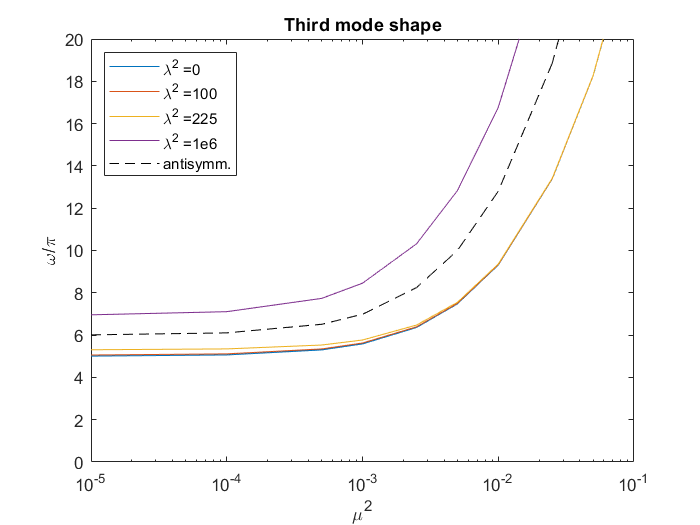

IndTitle = {'First','Second','Third'};
indLim = [6,12,20];
clf;close all;
for ii=1:3
    figure
    hold on; box on;
    plot(mu.^2,w_s(:,:,ii)./pi);
    plot(mu.^2,w_a(:,:,ii)./pi,'k--');
    set(gca,'xscale','log');
    legend('\lambda^2 =0','\lambda^2 =100','\lambda^2 =225','\lambda^2 =1e6','antisymm.','location','NorthWest')
    xlabel('\mu^2')
    ylabel('\omega/\pi')
    title([IndTitle{ii},' mode shape'])
    ylim([0,indLim(ii)]);
    set(gcf,'color','w');
end

## Evolution of mode shapes with lambda and mu

Figure 3 from [1] is reproduced

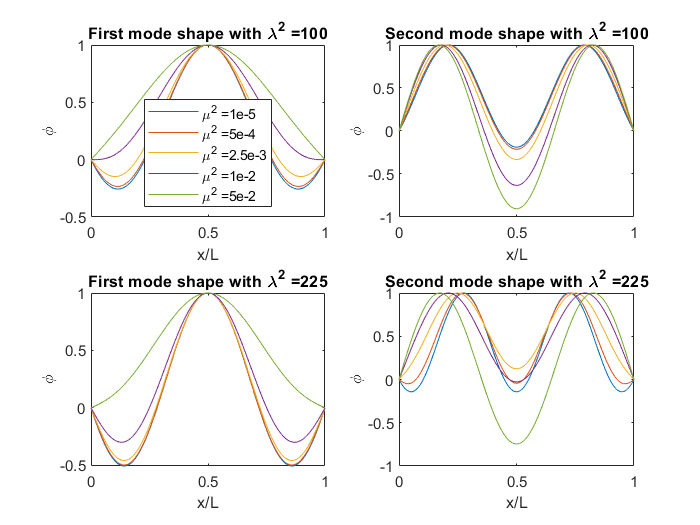


clf;close all;
figure
jj=1;
IndTitle = {'First','Second','First','Second',};
legLambda = [100,100,225,225];
indLambda = [2,2,3,3];
indMode = [1,2,1,2];
for ii=1:4
    subplot(2,2,ii)
    hold on; box on;
    plot(x,squeeze(phi_s(indLambda(ii),2:2:end,indMode(ii),:)));
    if ii==1
        legend('\mu^2 =1e-5','\mu^2 =5e-4','\mu^2 =2.5e-3','\mu^2 =1e-2','\mu^2 =5e-2','location','South')
    end
    xlabel('x/L')
    ylabel('\phi')
    title([IndTitle{ii},' mode shape with \lambda^2 =',num2str(legLambda(ii))])
    set(gcf,'color','w');
end

## Conclusions

The numerical implementation seems ok. However, numerical issues may occur if the options "tolFun" and "tolX" in the fsolve function are higher than 1e-8. The user is welcome to try 1e-6 or higher and see the differences.